% Read the data from source
%{
% Source_1 : https://ec.europa.eu/eurostat/databrowser/view/DS-018995__custom_5664444/default/table?lang=en
[imports, countries] = get_eu_adjacency('europe_imports.csv'); % from rows to columns
[exports, countries] = get_eu_adjacency('europe_exports.csv'); % from columns to rows
net_exports = max(exports - imports', 0);
adjacency_matrix = exports;
node_labels = countries;
save_name = "exports";
show_labels = true;
%}

%Source_2 : websites
save_name = "manchester_depth_3"

save_name = "manchester_depth_3"

load(save_name + ".mat", "adjacency_matrix", "node_labels")
[adjacency_matrix, remaining_nodes] = remove_unconnected_nodes(adjacency_matrix);
%node_labels = links;
node_labels = node_labels(remaining_nodes)';
show_labels = false;


% Create save folder
save_folder = "results/" + save_name + "/"

save_folder = "results/manchester_depth_3/"

if  ~exist(save_folder, 'dir')
    mkdir(save_folder);
end
save_name = save_folder + save_name + "_"

save_name = "results/manchester_depth_3/manchester_depth_3_"


% Get Pageranks
n = size(adjacency_matrix, 1); 
e = ones(n, 1);
p = pagerank(adjacency_matrix, 0.85, e/n, 50);
col_sums = e' * adjacency_matrix;
col_sums = col_sums';
row_sums = adjacency_matrix* e;

% Col sum table (out links)
[sorted_outgoing, indicies] = sort(col_sums, 'descend');
col_sum_table = table(sorted_outgoing, node_labels(indicies))

col_sum_table = 1821×2 table
    sorted_outgoing                                        Var2                                    
    _______________    ____________________________________________________________________________

          116          {'https://wordpress.org/'                                                  }
          115          {'https://blog.policy.manchester.ac.uk/wp-login.php'                       }
          115          {'https://www.studiopress.com/'                                            }
          114          {'http://blog.policy.manchester.ac.uk'                                     }
          114          {'http://feeds.feedburner.com/ManchesterPolicyBlogs'                       }
          114          {'http://www.policy.manchester.ac.uk/'                                     }
          114          {'http://www.policy.manchester.ac.uk/about/'                               }
  


% Row sum table (in links)
[sorted_outgoing, indicies] = sort(row_sums, 'descend');
row_sum_table = table(sorted_outgoing, node_labels(indicies))

row_sum_table = 1821×2 table
    sorted_outgoing                                                    Var2                                                 
    _______________    _____________________________________________________________________________________________________

          186          {'https://www.manchester.ac.uk/discover/news/tagfeed/en/tags/arts,humanities,society,society-arts'  }
          171          {'https://www.manchester.ac.uk/discover/news/tagfeed/en/tags/humanities'                            }
          161          {'https://www.manchester.ac.uk/discover/news/tagfeed/en/tags/university-news,University__news'      }
          151          {'http://www.staffnet.manchester.ac.uk/'                                                            }
          148          {'https://www.manchester.ac.uk/discover/news/tagfeed/en/tags/health'                                }
          144          {'ht


% Pagerank table
pr_table = pr_ranking_table(adjacency_matrix, node_labels)

pr_table = 100×2 table
    top_page_ranks                                     top_node_labels                                  
    ______________    __________________________________________________________________________________

         0.1533       {'https://www.manchester.ac.uk'                                                  }
        0.11308       {'http://www.manchester.ac.uk/discover/news/'                                    }
       0.030826       {'https://www.manchester.ac.uk/discover/news/?h=1&t=science-and-engineering'     }
       0.021478       {'https://www.manchester.ac.uk/discover/news/?h=1&t=arts'                        }
        0.02007       {'http://www.staffnet.manchester.ac.uk/'                                         }
       0.016628       {'https://www.manchester.ac.uk/discover/news/?h=1&t=Research-Beacons'            }
        0.01523       {'https://www.manchester.ac.uk/discover/news/?

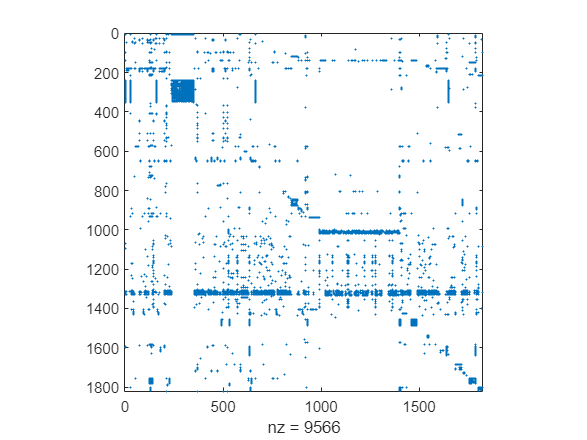

% Adjacency matrix
figure;
spy(adjacency_matrix);

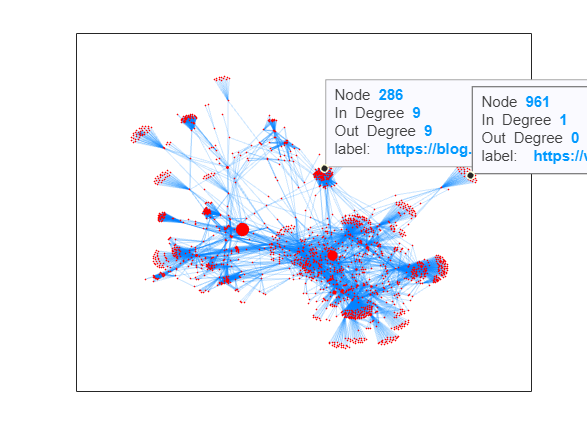

adjacency_plot = gcf;

% Graph
figure;
graph = digraph(adjacency_matrix);
gp = plot(graph, 'layout', 'force','NodeLabel', {});
graph_plot = gp;
gp.EdgeColor = [0,0.5,1];
gp.EdgeAlpha = 0.2;
gp.ShowArrows = "off";

% Weighting graph by size of edge weights
marker_max = 20;
gp.NodeColor = "red";
gp.MarkerSize = 50*p + 0.2;

row = dataTipTextRow('label: ',node_labels);
gp.DataTipTemplate.DataTipRows(end+1) = row;

% Add text next to each node
if show_labels
    for i = 1:numel(node_labels)
        text(gp.XData(i) + 0.1, gp.YData(i), node_labels(i), 'FontSize', 12);
    end
end

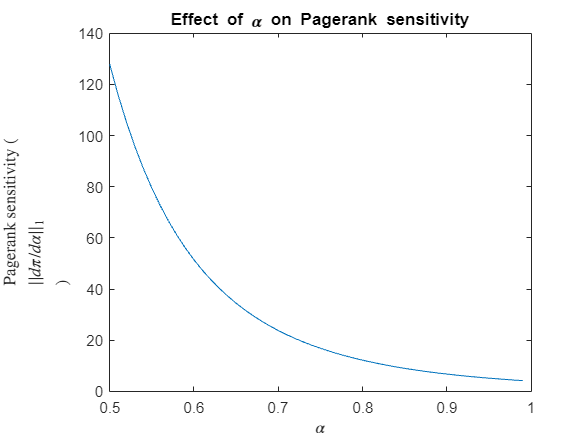

% Testing how sensitivity changes wrt alpha parameter
figure;
alpha_values = .5:.01:.99;
sensitivities = [];
v = e/n;
for i = 1:numel(alpha_values)
    sensitivity_vector = pr_alpha_sensitivity(adjacency_matrix, alpha_values(i), v);
    sensitivities(end + 1) = norm(sensitivity_vector, 1);
end
sensitivity_plot = plot(alpha_values, sensitivities);
xlabel("$$\alpha$$", "Interpreter","latex");
ylabel("Pagerank sensitivity ($$|| d \pi / d \alpha||_1$$)", "Interpreter","latex");
title("Effect of \alpha on Pagerank sensitivity")

% Saving everything
table2latex(col_sum_table(1:10, :), char(save_name + "out_links_table") );
table2latex(row_sum_table(1:10, :), char(save_name + "in_links_table"));
table2latex(pr_table(1:10, :), char(save_name + "pr_table"));
saveas(adjacency_plot, save_name + "adjacency", "png");

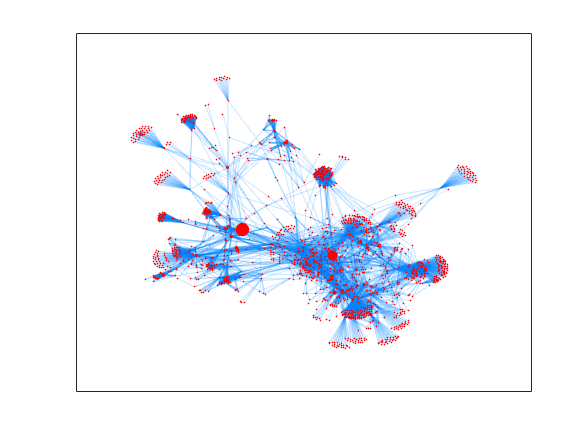

saveas(graph_plot, save_name + "graph", "png");

saveas(sensitivity_plot, save_name + "sensitivity_plot", "png");